## Spectrogram Generation 

### Control Signals

% Locate the TVALID and TLAST control signals of the FFT
fft_out_tvalid = out.TVALID

fft_out_tvalid =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


find(fft_out_tvalid == 1, 1)

ans = 4237

fft_out_tlast = out.TLAST

fft_out_tlast =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


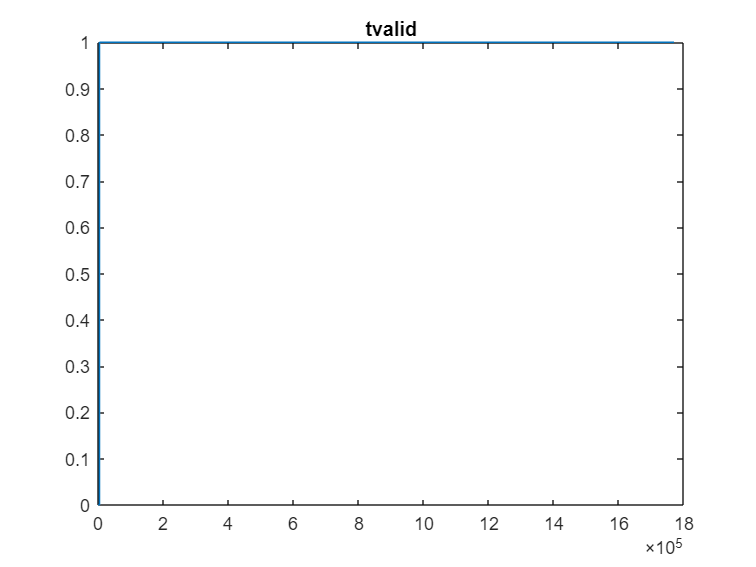

plot(1:length(fft_out_tvalid),fft_out_tvalid)
title('tvalid')

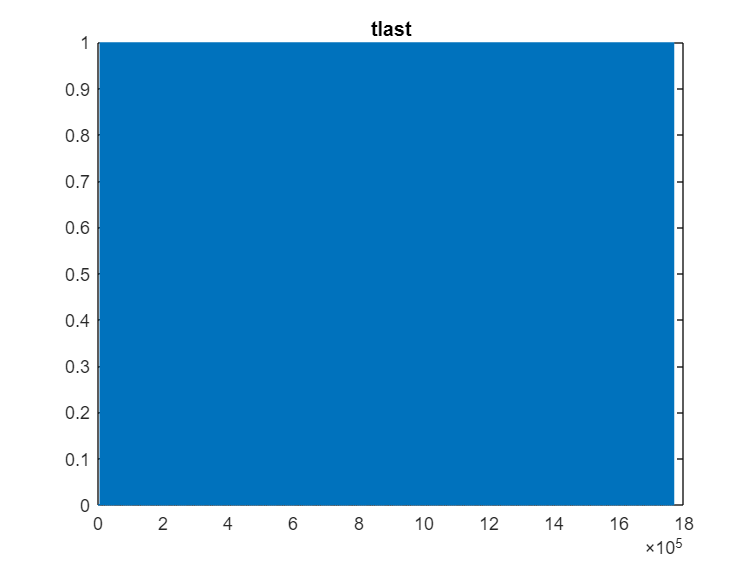

plot(1:length(fft_out_tlast),fft_out_tlast)
title('tlast')


% Set TLAST signal from first TVALID to keep it with data output
fft_out_tlast = fft_out_tlast(find(fft_out_tvalid == 1, 1):end)

fft_out_tlast =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


find(fft_out_tlast,1,'first')

ans = 2048


% Locate the FFT data output
fft_out_log_ = out.FFT_out_log

fft_out_log_ =      0
     0
     0
     0
  -128
  -128
  -128
  -128
  -128
  -128


% Only keep the valid samples
fft_out_log = fft_out_log_(find(fft_out_tvalid == 1, 1):end)

fft_out_log =   -128
  -128
  -128
  -128
  -128
  -128
  -128
  -128
  -128
  -128


% Zero-pad if neccessary to ensure # samples is an integer multiple of the
% window size (required for easier spectrogram plotting)
fft_length_before_zero_padding = (ceil(length(fft_out_log)/N))

fft_length_before_zero_padding = 862


% Set the zero-padded values to the minimum value of the valid samples
fft_out_log(length(fft_out_log)+1:fft_length_before_zero_padding*N)=min(fft_out_log)

fft_out_log =   -128
  -128
  -128
  -128
  -128
  -128
  -128
  -128
  -128
  -128


### HDL block floating point 

% Determine key parameters
Total_Num_Samples = length(fft_out_log)

Total_Num_Samples = 1765376

Num_Segments = Total_Num_Samples/N

Num_Segments = 862


% Create the frequency and time axis for both spectrograms
f_axis_1N = (n/N*fs)/1e6; % From 0 -> fs
f_axis_1N_ = (-N/2:N/2-1)*(fs/N)/1e6; % From -fs/2 -> fs/2 (combined with fftshift for centring DC - as high f is just a spectral replication of -ve f)
t_axis_1N = linspace(0,Total_Num_Samples/fs,Num_Segments)

t_axis_1N =          0    0.0001    0.0003    0.0004    0.0005    0.0006    0.0008    0.0009    0.0010    0.0012    0.0013    0.0014    0.0015    0.0017    0.0018    0.0019    0.0021    0.0022    0.0023    0.0024    0.0026    0.0027    0.0028    0.0029    0.0031    0.0032    0.0033    0.0035    0.0036    0.0037    0.0038    0.0040    0.0041    0.0042    0.0044    0.0045    0.0046    0.0047    0.0049    0.0050    0.0051    0.0053    0.0054    0.0055    0.0056    0.0058    0.0059    0.0060    0.0062    0.0063


t_axis_1N = 1e3.*t_axis_1N

t_axis_1N =          0    0.1281    0.2563    0.3844    0.5126    0.6407    0.7689    0.8970    1.0252    1.1533    1.2815    1.4096    1.5378    1.6659    1.7941    1.9222    2.0504    2.1785    2.3067    2.4348    2.5630    2.6911    2.8193    2.9474    3.0756    3.2037    3.3319    3.4600    3.5882    3.7163    3.8445    3.9726    4.1008    4.2289    4.3571    4.4852    4.6134    4.7415    4.8696    4.9978    5.1259    5.2541    5.3822    5.5104    5.6385    5.7667    5.8948    6.0230    6.1511    6.2793


f_axis = repmat(f_axis_1N,1,Num_Segments)

f_axis =          0    0.0078    0.0156    0.0234    0.0312    0.0391    0.0469    0.0547    0.0625    0.0703    0.0781    0.0859    0.0938    0.1016    0.1094    0.1172    0.1250    0.1328    0.1406    0.1484    0.1562    0.1641    0.1719    0.1797    0.1875    0.1953    0.2031    0.2109    0.2188    0.2266    0.2344    0.2422    0.2500    0.2578    0.2656    0.2734    0.2812    0.2891    0.2969    0.3047    0.3125    0.3203    0.3281    0.3359    0.3438    0.3516    0.3594    0.3672    0.3750    0.3828


f_axis_ = repmat(f_axis_1N_,1,Num_Segments)

f_axis_ =    -8.0000   -7.9922   -7.9844   -7.9766   -7.9688   -7.9609   -7.9531   -7.9453   -7.9375   -7.9297   -7.9219   -7.9141   -7.9062   -7.8984   -7.8906   -7.8828   -7.8750   -7.8672   -7.8594   -7.8516   -7.8438   -7.8359   -7.8281   -7.8203   -7.8125   -7.8047   -7.7969   -7.7891   -7.7812   -7.7734   -7.7656   -7.7578   -7.7500   -7.7422   -7.7344   -7.7266   -7.7188   -7.7109   -7.7031   -7.6953   -7.6875   -7.6797   -7.6719   -7.6641   -7.6562   -7.6484   -7.6406   -7.6328   -7.6250   -7.6172


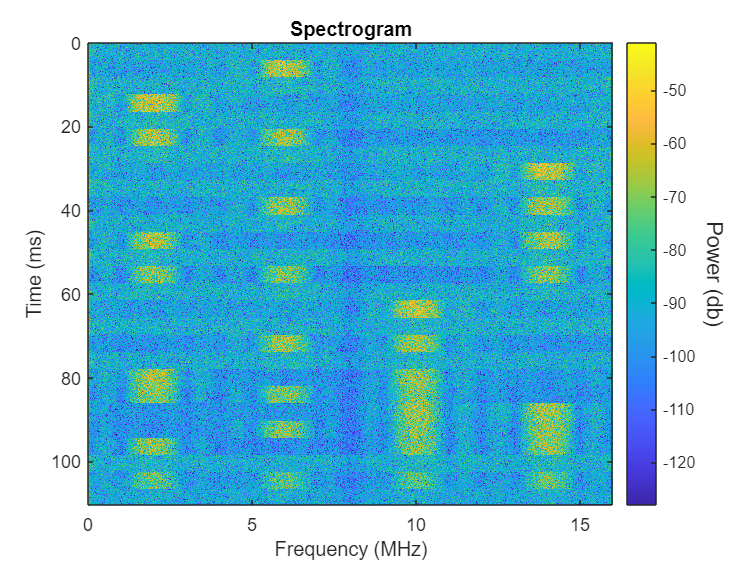


% Fill in the arrays to plot the spectrograms
for i=1:Num_Segments
    index = (i-1)*N+1 : i*N;
    t_axis(index) = t_axis_1N(i);   
    Data(i,:) = fft_out_log(index);
    Data_shift(i,:) = fftshift(Data(i,:));
end

% Plot spectrograms 
figure;
imagesc(f_axis,t_axis,Data)
title('Spectrogram')
xlabel('Frequency (MHz)')
ylabel('Time (ms)')
colorbar
cb = colorbar();  ylabel(cb,'Power (db)','FontSize',12,'Rotation',270)

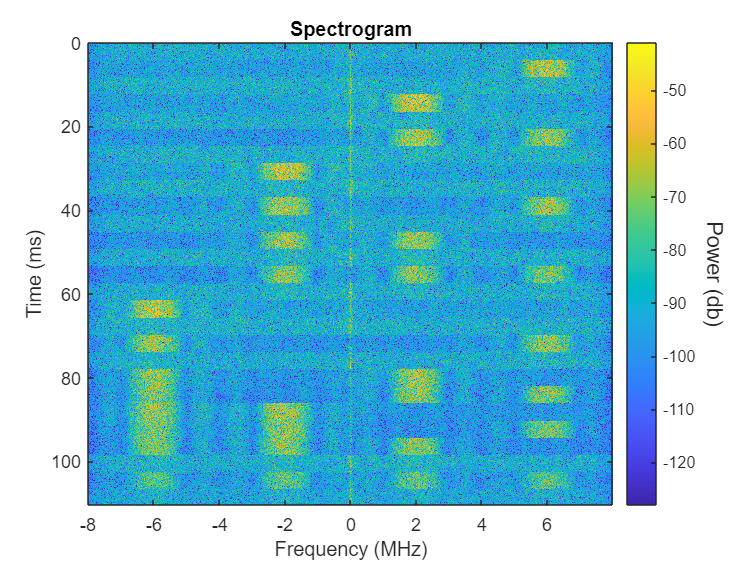

imagesc(f_axis_,t_axis,Data_shift)
title('Spectrogram')
xlabel('Frequency (MHz)')
ylabel('Time (ms)')
cb = colorbar();  ylabel(cb,'Power (db)','FontSize',12,'Rotation',270)

spectrum =   -128  -128  -128  -128  -128  -128  -128  -128  -128  -128  -128  -128  -128  -128  -128  -128  -128  -128  -128  -128  -128  -128  -128  -128  -128  -128  -128  -128  -128  -128  -128  -128  -128  -128  -128  -128  -128  -128  -128  -128  -128  -128  -128  -128  -128  -128  -128  -128  -128  -128


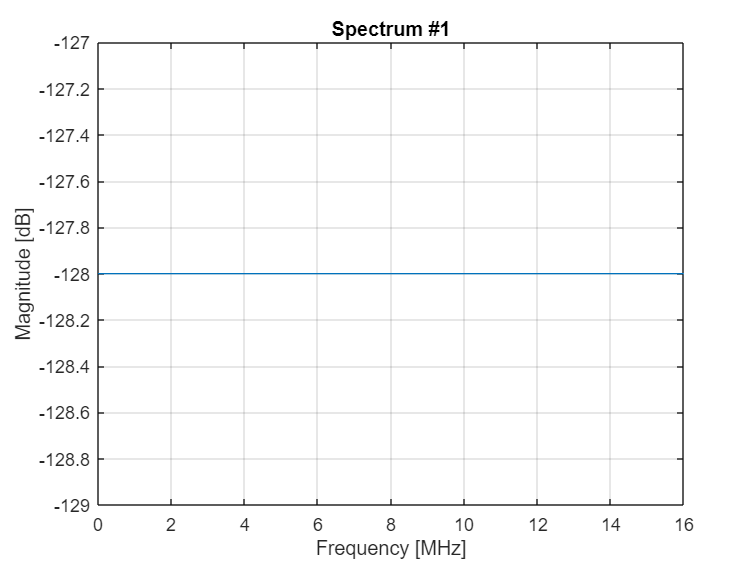

spectrum =   -94.2183  -93.4585  -82.8861  -89.4977  -99.8566  -87.2562  -92.7121 -109.8766  -92.1216  -89.9914  -92.4450 -101.7658  -91.9125  -85.7902 -104.7533  -95.7950  -87.6460  -93.8059  -94.7198 -102.6874  -97.3166  -96.3454 -107.6507 -100.5194 -103.1678 -100.4527  -94.1570  -90.9092 -104.1536  -91.9444  -98.4520 -109.1977 -104.8263  -94.9664  -82.0026  -81.0968  -98.6492  -84.8517 -100.3511 -102.6324  -95.1570  -94.5904 -122.0910 -113.0064  -96.0561  -94.5869  -95.0383  -92.9237  -97.1425 -106.5521


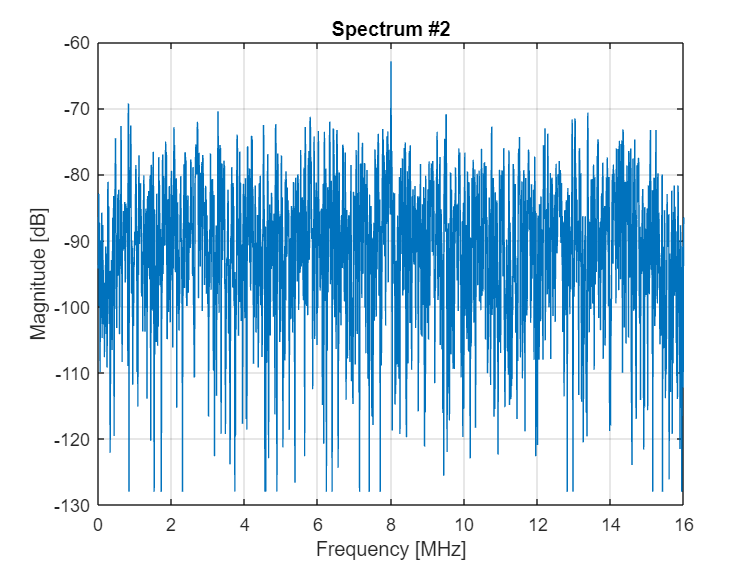

spectrum =  -102.8926  -91.9739  -96.4534  -98.1670 -120.9364  -94.2000  -92.0909  -97.7889 -100.7934  -95.6683  -98.3057 -118.7495  -90.4576  -85.3392  -90.0088  -98.6437  -93.7521  -87.5656  -94.5696  -98.0966 -107.3138 -102.8543  -89.7088  -88.7478  -84.3372  -93.3622 -102.7827  -98.0087  -96.8337  -99.7460  -88.0616  -93.3067 -127.5923  -93.8313  -82.8158 -111.2038  -93.6768  -82.2130  -85.8487 -112.3385  -97.8254 -128.0000  -93.1156 -105.2748 -108.0829 -113.0864 -106.2812  -96.8214  -85.7659  -97.1600


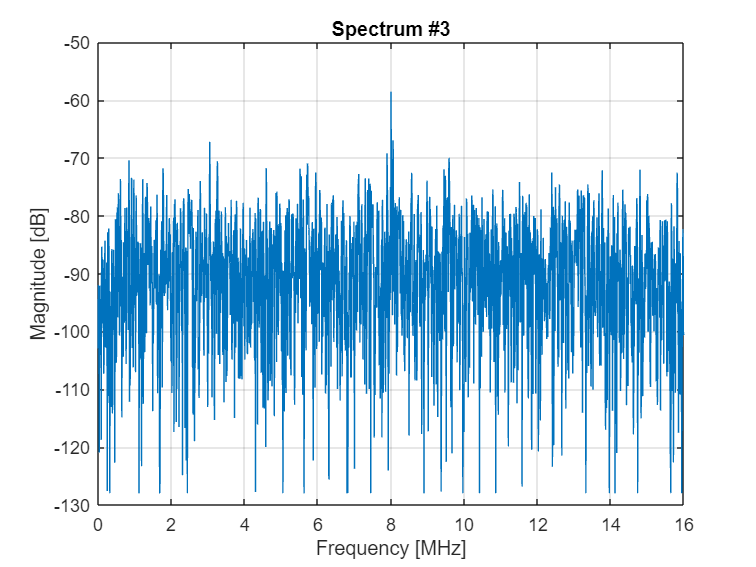

spectrum =   -85.8639  -84.9995  -94.2216  -93.7183 -107.8761 -102.4589  -83.5337  -80.2622  -83.9377 -106.5831  -97.5380 -100.1677  -90.6655  -82.8863  -80.1427  -85.4542  -93.4592  -95.7353  -88.7557  -92.5363 -128.0000  -97.6978  -90.3163  -92.6633  -87.0578 -112.1072  -90.1941  -95.0127 -116.4062  -96.2220  -82.6029  -89.3189 -102.8386 -101.0142  -95.1477 -113.0937  -97.9958  -99.6802 -104.8122 -112.3855  -97.7952  -76.6756  -80.6540 -104.6642  -82.8373  -90.2088 -106.7188  -96.5660  -93.0122  -82.3175


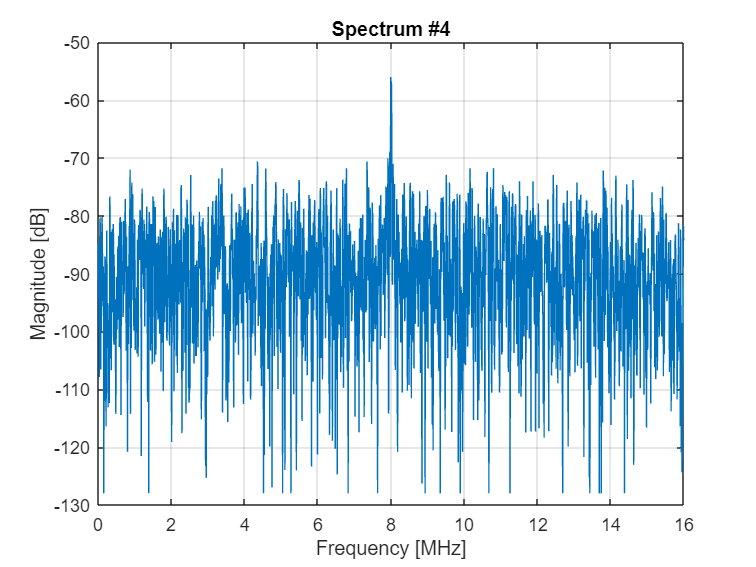

spectrum =  -101.7917  -91.1103  -89.6960  -96.0458 -115.4260  -88.3835  -85.3359  -93.9056  -89.0396  -88.6658  -90.4651 -113.4592  -89.0314  -97.6016 -103.4111  -92.9086  -98.3765 -104.0241  -96.4276  -87.3945  -94.4211 -118.6936 -101.6262  -98.8198  -98.5418  -91.2954  -86.8738 -112.0164  -95.1108  -92.0087 -107.9002 -108.2360  -93.7285  -97.3977 -114.1818  -95.9631  -94.0438 -109.5840 -102.1220  -81.6099  -81.5182  -97.7376 -126.9931 -102.5692  -89.1234  -87.6028  -83.5337  -90.5301  -91.3496  -89.8908


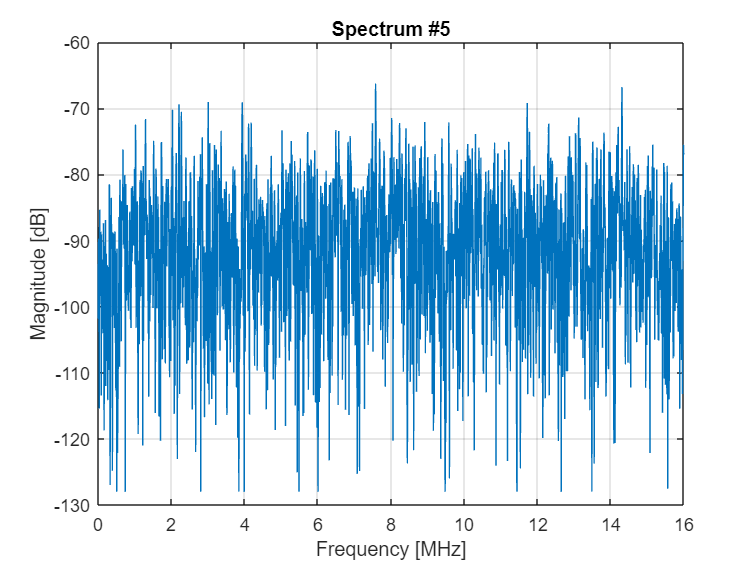

spectrum =   -89.3816 -105.9668  -99.3557  -96.1407  -99.0054  -94.3930 -115.6683 -108.1612 -128.0000 -100.5453  -93.8488 -103.4616  -87.3862  -83.8455  -88.6238  -89.3921 -122.1117  -94.2817  -99.5687  -91.2144 -100.0302 -113.6596  -86.3970  -90.8131  -95.3367 -105.7917  -88.2578  -86.3340 -128.0000 -103.2098  -94.3837  -82.3824  -94.5161  -88.6211  -82.8561  -89.2553  -99.4966  -96.6822  -93.2633 -105.3944  -99.6460  -82.6537  -83.1434  -93.4030  -92.8346  -91.4337  -91.3532  -94.7154  -97.7601  -95.2520


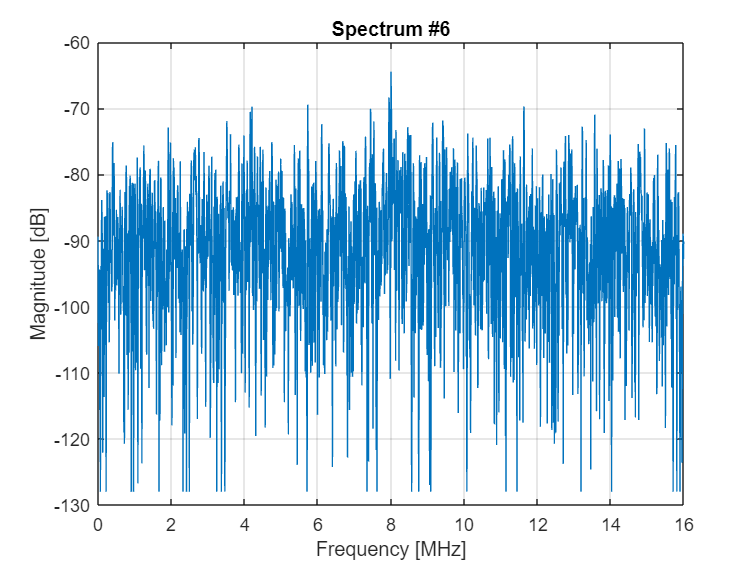

spectrum =   -86.0749  -88.9074  -94.7959 -123.0705 -114.1570  -86.7716  -81.3450  -86.2698  -81.1787  -81.7655 -102.2952  -94.4560  -82.2385  -96.7398  -92.6258  -89.4639  -83.2792  -84.8072  -95.2053  -97.9817 -110.1690 -117.2834  -93.7301  -89.1935  -90.4608  -86.8981  -82.2309  -86.1794  -95.6467  -94.4989 -106.5624  -94.4458  -93.1678  -86.4815  -79.1433  -91.1558 -100.6179 -110.5967  -89.9313  -89.5432 -115.5028 -100.8843 -100.7210  -88.3690  -83.7304  -81.7449  -84.1167  -82.4736  -83.9675  -99.3813


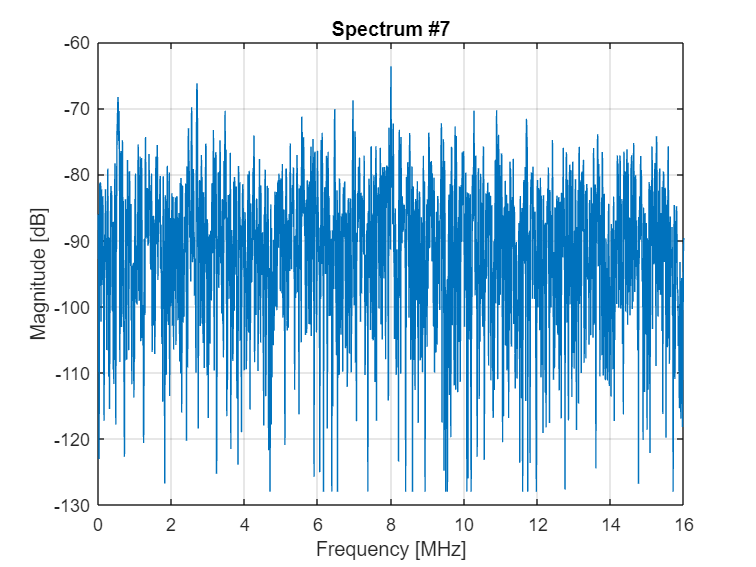

spectrum =   -95.6349  -97.9191 -109.4678  -93.3261  -90.3600  -94.4834 -106.7610  -89.0273 -100.6179  -97.7601  -91.9406  -91.9368 -116.6668 -105.9572  -87.6417  -89.8761  -85.6093  -88.4534  -87.1376  -90.3974 -105.1597 -105.0404  -86.2005  -93.0275 -111.5699 -115.5124  -86.5666  -81.2227 -101.2894  -93.0776  -92.1425 -108.8772  -97.4362  -81.0233  -79.2272  -90.2957 -127.9082 -100.1249  -85.4306  -86.5198 -100.5729 -104.0783  -98.7103  -91.2687  -89.2849 -101.4142 -103.6271  -96.9332  -83.0548  -83.7877


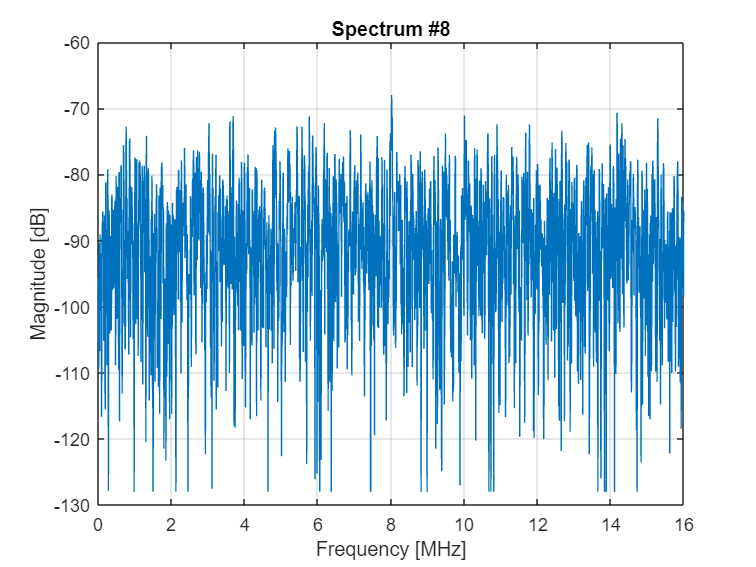

spectrum =   -98.9021  -97.7676  -88.4710  -84.2772  -84.1942  -92.9237  -94.2350  -90.1617  -88.5568 -102.2050  -89.9343  -92.6758  -97.6755  -84.3442  -80.8396 -105.2956  -91.2901  -91.4198 -100.9472 -128.0000 -100.9779  -88.1224  -95.3841 -118.6381  -93.6363  -91.5064  -83.0271  -84.7349  -87.4379 -104.7003 -103.4111  -94.6304  -98.9450 -112.7429  -91.3855  -87.7276  -85.6263  -81.7964  -89.7420  -86.9455  -89.4207 -113.1010  -97.2221  -94.5991 -104.8772  -84.0599  -86.7864 -111.3520  -98.8623 -106.2180


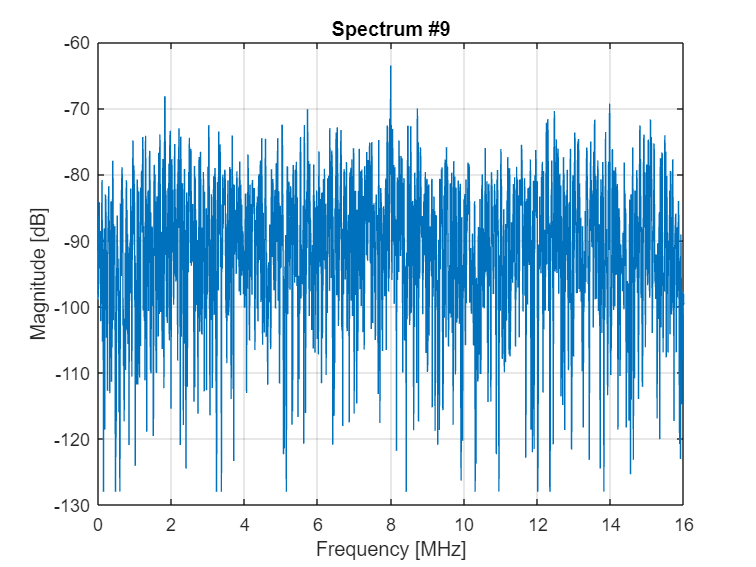

for idx = 1:9
    % Plot idx spectrum 
    spectrum = Data_shift(idx,:)
    figure;
    plot(f_axis_1N,spectrum);
    xlabel('Frequency [MHz]');
    ylabel('Magnitude [dB]');
    title(sprintf('Spectrum #%s',num2str(idx)));
    grid on;
end